# Materials classification - A1

clc; clear all; close all;

## Import dataset

image_data_folder = "Data\image\";
mask_data_folder = "Data\mask\";
image = Images_import(image_data_folder);
mask = Images_import(mask_data_folder);

% Each row of each matrix contains the paths of the images of an specific material, being
% the order of the rows: fabric, foliage, glass, leather, metal, paper,
% plastic, tone, water and wood
% Now, to have acces to an image we only have to do:
% imread(image(i,j)) or imread(mask(i,j))

## Create targets

for idx = 1:length(image)
    if contains(image(idx).path, "fabric")
        image(idx).target = "fabric";
        mask(idx).target = "fabric";
    elseif contains(image(idx).path, "foliage")
        image(idx).target = "foliage";
        mask(idx).target = "foliage";
    elseif contains(image(idx).path, "glass")
        image(idx).target = "glass";
        mask(idx).target = "glass";
    elseif contains(image(idx).path, "leather")
        image(idx).target = "leather";
        mask(idx).target = "leather";
    elseif contains(image(idx).path, "metal")
        image(idx).target = "metal";
        mask(idx).target = "metal";
    elseif contains(image(idx).path, "paper")
        image(idx).target = "paper";
        mask(idx).target = "paper";
    elseif contains(image(idx).path, "plastic")
        image(idx).target = "plastic";
        mask(idx).target = "plastic";
    elseif contains(image(idx).path, "stone")
        image(idx).target = "stone";
        mask(idx).target = "stone";
    elseif contains(image(idx).path, "water")
        image(idx).target = "water";
        mask(idx).target = "water";
    elseif contains(image(idx).path, "wood")
        image(idx).target = "wood";
        mask(idx).target = "wood";
    end
end

### Create test image set

% Apply the mask and save only the foreground object
imgData = [];
for idx = 1:length(image)
    tempImg = im2gray(imread(image(idx).path));
    tempMask = im2gray(imread(mask(idx).path));
    tempImg(~tempMask) = 0;
    imgData{idx} = tempImg;
end

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];

## Feature Extraction

### Feature 1: Entropy measure

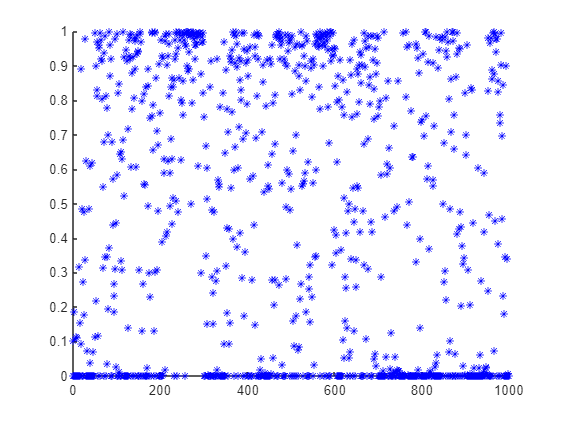

entropyVals = [];
for idx = 1:length(imgData)
    entropyVals(idx) = entropy(double(imgData{idx}(:)));
end
figure; hold on;
for idx = 1:length(imgData)
    plot(idx, entropyVals(idx), 'b*');
end
hold off;

### Feature 2: Number of edges

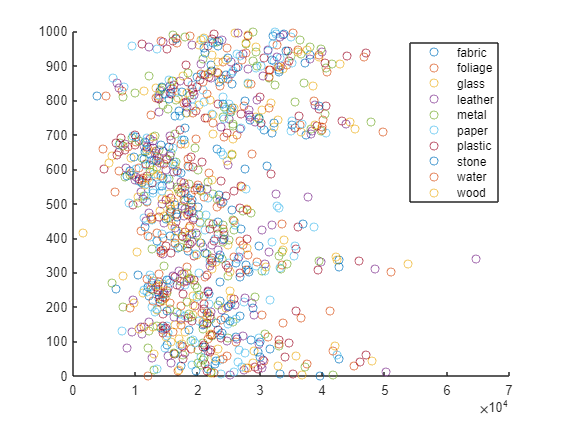

edgeCount = [];
for idx = 1:length(imgData)
    bw = edge(imgData{idx},'canny');
    edgeCount(idx) = nnz(bw);
end

figure; hold on;
for idx = 1:length(imgData)
    plot(edgeCount(idx), idx, 'o');
end
hold off;
legend(inputs);

### Feature 3: Std. deviation of image

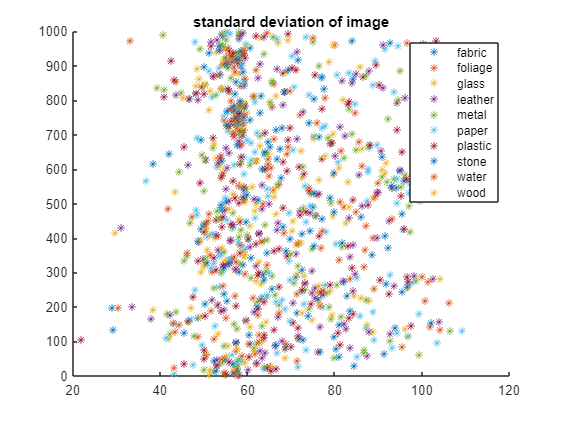

figure; hold on;
for idx = 1:length(imgData)
    imgDev = std(double(imgData{idx}(:)));
    plot(imgDev, idx, '*');
end
title("standard deviation of image")
hold off;
legend(inputs);

## Dividing the variables that need discretization

rng('default')

addpath(genpath('C:\Users\xènia\Desktop\advanced_data_analysis_and_machine_learning\byesian_network_application\bnt-master\bnt-master\BNT'))
load edgeCount.mat;
load entropyVals.mat;
load imgDev.mat;

Data= [edgeCount; entropyVals; imgDev ]';

nseg = 5;
data = Data;
data(:,end+1) = grp2idx(categorical(Data(:,1)));


for i = 1:length(data(1,1:end-1))

    var     = data(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end

    for ii = 1:nseg-1
        idxCurrent = intersect(find(data(:,i)>=seg(ii).LB), find(data(:,i)<seg(ii+1).LB));
        data2(idxCurrent,i) = ii;
    end

    idxCurrent = find(data(:,i)>seg(ii+1).LB);
    data2(idxCurrent,i) = ii+1;

end

data2(:,end+1) = data(:,end);




## Data Division

[row, col]      = size(data2);
varLabels = Data.Properties.VariableNames([2:end, 1]);

Dot indexing is not supported for variables of this type.


ii = 1;
for i = 1:col
    subplot(2, col, i);
    histogram(data(:,i)); title("Original " + varLabels(i));

    subplot(2, col, i+col);
    histogram(data2(:,i)); title("Discretized " + varLabels(i));
end



% Test and calibration in the partition below.
c       = cvpartition(data(:,end), 'Holdout', 0.2);
idxTest = test(c);
idxCal  = training(c);


dataAll  = data2;
data2    = [];
data2    = dataAll(idxCal,  :);
dataTest = dataAll(idxTest, :);


## Learn the structure of a BN

ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(data2');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(data2(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 2, 'verbose', 'yes');

BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end


figure;
draw_graph(BNhat.dag, varLabels);
title('Estimated BN structure');


## Classification

engine       = global_joint_inf_engine(BNhat);
[rowT, colT] = size(dataTest);


for j = 1:rowT
    for i = 1:col-1
        evidence     = [];
        evidence     = cell(1,colT);
        evidence{variable(i).node} = dataTest(j,i);
    end
    [engine, logLikelihood] = enter_evidence(engine, evidence);
    marginal       = marginal_nodes(engine, variable(end).node);
    totProb        = sum(marginal.T(:));
    dataPoint(j).M = marginal.T ./ totProb;
    [~, dataPoint(j).yhat] = max(dataPoint(j).M);
end

a = categorical([dataPoint.yhat]');
b = categorical(dataTest(:,end));

p1 = find(a == b, 1, 'first');
p2 = find(a ~= b, 1, 'first');

figure;
subplot(2,1,1);
bar(dataPoint(p1).M);
title("Probabilities of a correctly predicted sample")
subplot(2,1,2);
bar(dataPoint(p2).M);
title("Probabilities of an uncorrectly predicted sample")

figure;
confusionchart(a,b);
xlabel("Predicted")
ylabel("True Values")

aa = confusionmat(a,b);
accuracy = sum(diag(aa))/sum(sum(aa));

